設定

n_fft = 4096;                   %fft幅
n_shift = 16;                  %シフト幅
frame_size = 1024;              %フレームサイズ
n_audio = length(audio_in);     %音声ファイルの長さ
Fs = 44100;

メインループ

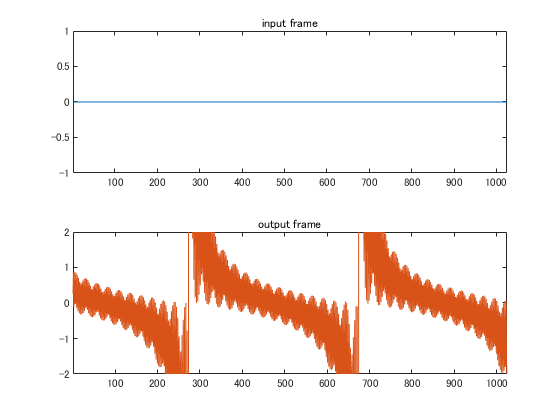

audio_in = zeros(2^15,1);
audio_out = [];

n = n_fft - n_shift;

%バッファ
x_buff = zeros(n_fft,2);
y_buff = zeros(n_fft,2);
s_buff = zeros(n_fft,2);
s = 0;
f = 55;
bins = 128;

for t = 1:frame_size:(n_audio-frame_size)
    x_frame = audio_in(t:t+frame_size,:);
    y_frame = zeros(frame_size,2);
    for i = 1:frame_size

        s = mod(s + f/Fs, 1);
        N = 1:bins;
        Phi = zeros(size(N));
        s_buff(n,:) = series2wave(2*pi*2*s-1,N,Phi);
        
        y_frame(i,:) = y_buff(max(1,n-n_fft/2),:);
        n = n + 1;
        if n == n_fft
            s_fft_allfreq = fft(s_buff,n_fft);
            s_fft = s_fft_allfreq(1:end/2,:).*2;
            s_buff(1:end-n_shift,:) = s_buff(n_shift+1:end,:);
            y_fft = s_fft;
            y_buff = real(ifft(y_fft,n_fft));
            n = n_fft-n_shift;
        end
    end
    
    tiledlayout(2,1);
    
    nexttile;
    plot(x_frame);
    ylim([-1,1]);
    xlim([-inf inf])
    title("input frame")
    
    nexttile;
    plot(y_frame);
    ylim([-2,2]);
    xlim([-inf inf])
    title("output frame")
    
    drawnow;
    
    audio_out = [audio_out; y_frame]; 
end

soundsc(audio_out,Fs);


function y = series2wave(x,N,Phi)
    n = length(N);
    y = 0;
    for i = 1:n
        y = y + sin(N(i)*x+Phi(i))/N(i);
    end
end